# Robot PKM

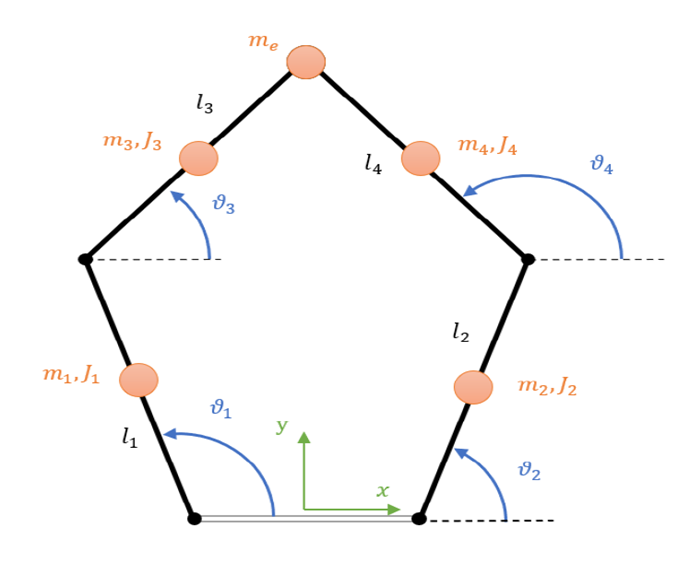

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot();

% Definizione parametri di test
theta1 = deg2rad(120); % Condizione iniziale posizione Theta1
theta2 = deg2rad(60); %  Condizione iniziale posizione Theta2
thetaV = deg2rad(720); % Angolo proprio della vite

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
thetaV_p = 0; % Velocita thetav di prova

theta1_pp = 0; %  Condizione iniziale accelerazione theta1
theta2_pp = 0; %  Condizione iniziale accelarazione theta2
thetaV_pp = 0; % Accelerazione thetav di prova

## Legge di moto

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


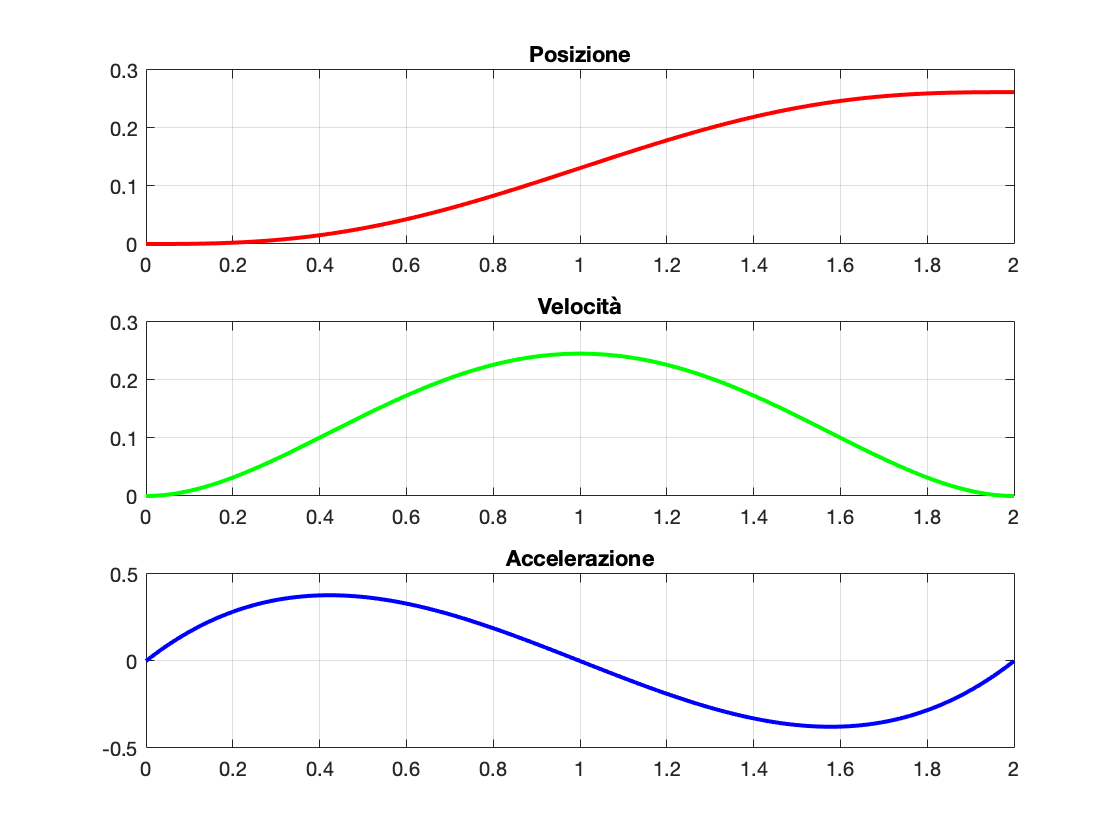

Ldm_theta1 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0761    0.0781    0.0801    0.0821    0.0841    0.0861    0.0881    0.0901    0.0921    0.0941    0.0961    0.0981


[Ldm_theta1,time] = Define_ldm(deg2rad(15), 'pol345') % Definisce una legge di moto data l'alzata in gradi per theta1

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


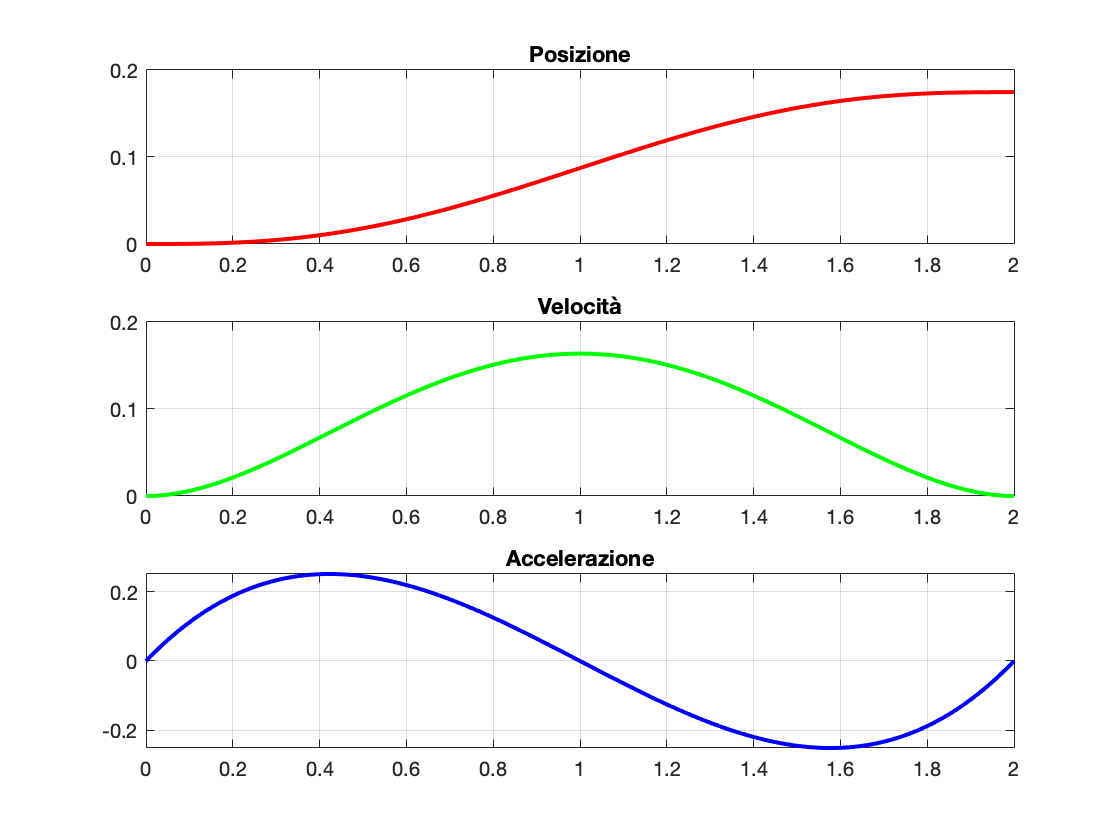

Ldm_theta2 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0761    0.0781    0.0801    0.0821    0.0841    0.0861    0.0881    0.0901    0.0921    0.0941    0.0961    0.0981


[Ldm_theta2,time] = Define_ldm(deg2rad(10), 'pol345') % Definisce una legge di moto data l'alzata in gradi per theta2

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


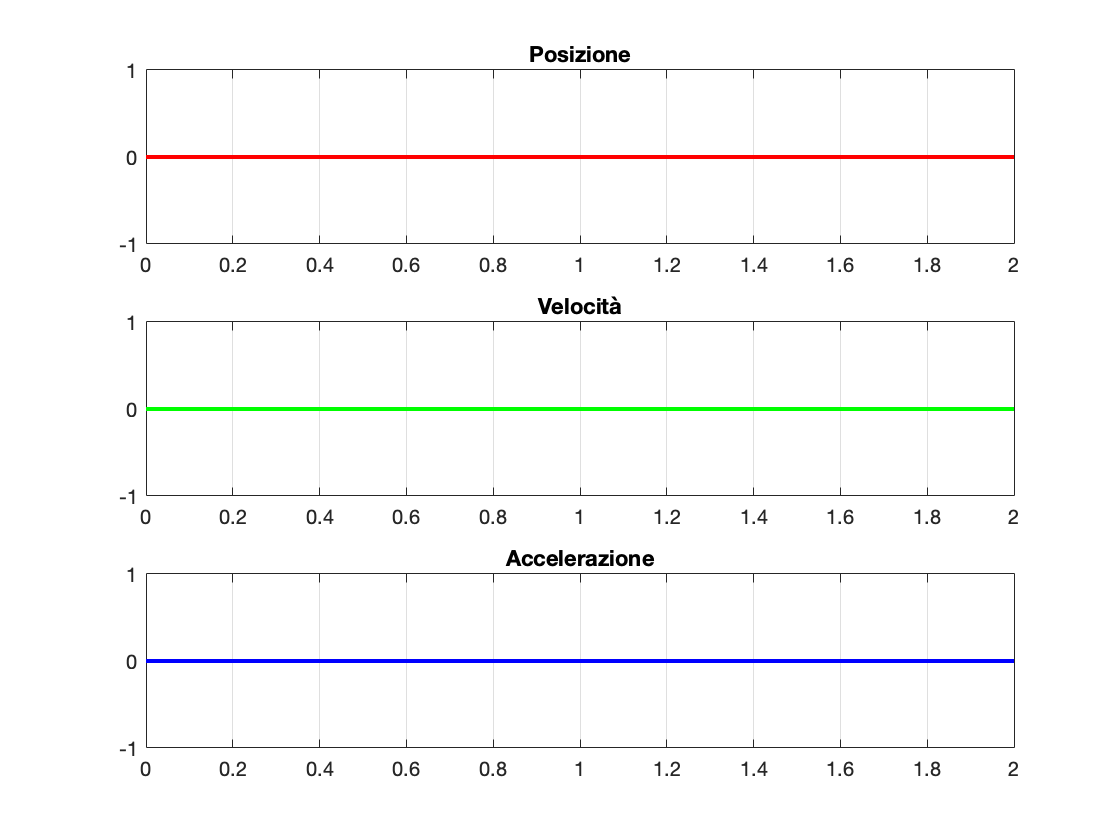

Ldm_thetav = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


time =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0761    0.0781    0.0801    0.0821    0.0841    0.0861    0.0881    0.0901    0.0921    0.0941    0.0961    0.0981


[Ldm_thetav,time] = Define_ldm(0, 'pol357') % Definisce una legge di moto per la vite


theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;
thetavldm = thetaV + Ldm_thetav.moto.data{1,1}.v;
PKM.ta = Ldm_theta1.vldm{1,1}.ta+Ldm_theta1.vldm{1,2}.ta+Ldm_theta1.vldm{1,3}.ta+Ldm_theta1.vldm{1,4}.ta;

Theta = [theta1ldm; theta2ldm; thetavldm]

Theta =     2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0946    2.0946    2.0946    2.0946    2.0946    2.0946    2.0946    2.0946    2.0947    2.0947
    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0474    1.0474    1.0474 

## Cinematica diretta

**Analisi di posizione**

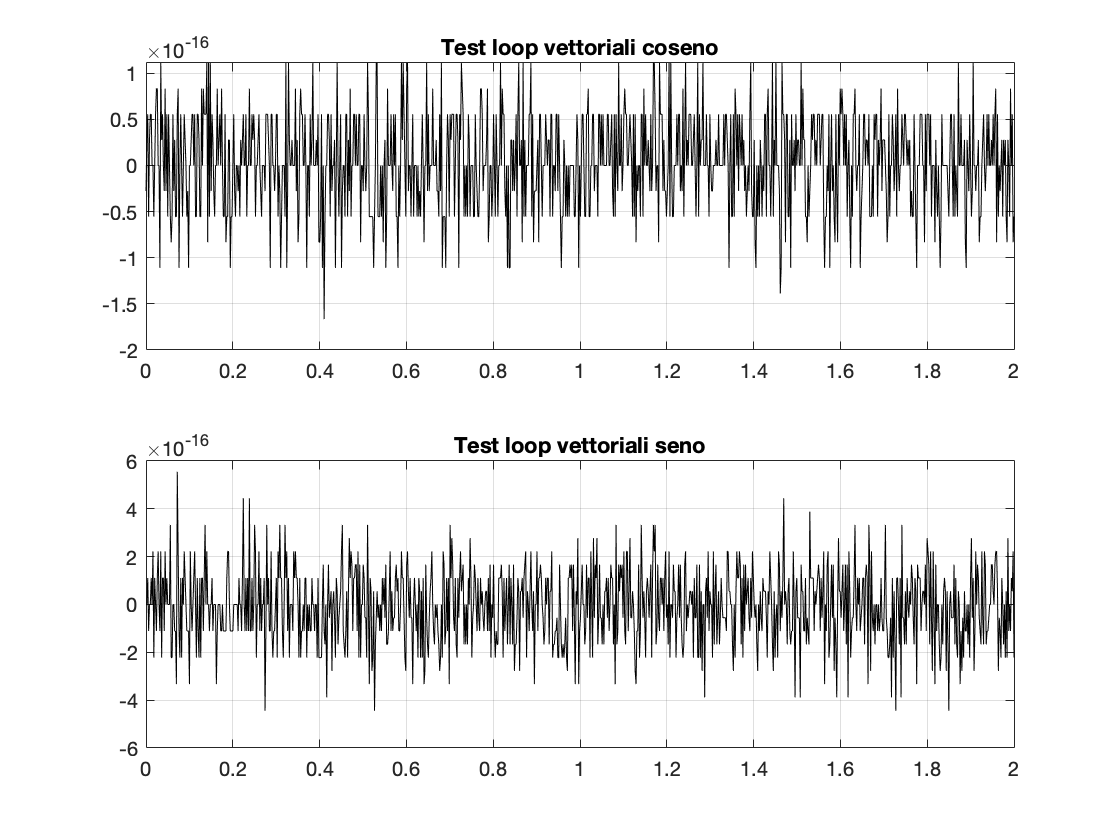

P =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0

theta3 =     0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356


theta4 =     2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6063    2.6063    2.6063


E1 =    -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2151   -0.2151   -0.2151   -0.2151
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    

E2 =     0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione(PKM, theta1ldm, theta2ldm, thetavldm,time)

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1ldm,theta2ldm,theta3,theta4)

**Analisi di velocità**

theta1ldm_p = theta1_p + Ldm_theta1.moto.data{2,1}.v;
theta2ldm_p = theta2_p + Ldm_theta2.moto.data{2,1}.v;
thetavldm_p = thetaV_p + Ldm_thetav.moto.data{2,1}.v;

[P_p, J, P_pM] = Cinematica_Diretta_Velocita2(PKM, theta1ldm, theta2ldm, theta1ldm_p,theta2ldm_p,thetavldm_p,P)

P_p =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0010   -0.0010   -0.0011   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0015   -0.0015   -0.0016   -0.0017   -0.0018   -0.0018   -0.0019   -0.0020   -0.0021
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0007   

J =    -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453
   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0

P_pM =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0010   -0.0011   -0.0011   -0.0012   -0.0012   -0.0013   -0.0014   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0018   -0.0019   -0.0020   -0.0020   -0.0021


Theta_p = [theta1ldm_p;theta2ldm_p;thetavldm_p]

Theta_p =          0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0014    0.0015    0.0017    0.0018    0.0020    0.0022    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0036    0.0038    0.0040    0.0042    0.0045    0.0047    0.0050    0.0053    0.0055    0.0058    0.0061    0.0064    0.0067    0.0070    0.0073    0.0076    0.0079    0.0082    0.0085
         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0027    0.0028    0.0030    0.0032    0.0033    0.0035    0.0037    0.0039    0.0041    0.0042    0.0044    0.0046    0.0048    0.0051    0.0053    0.005

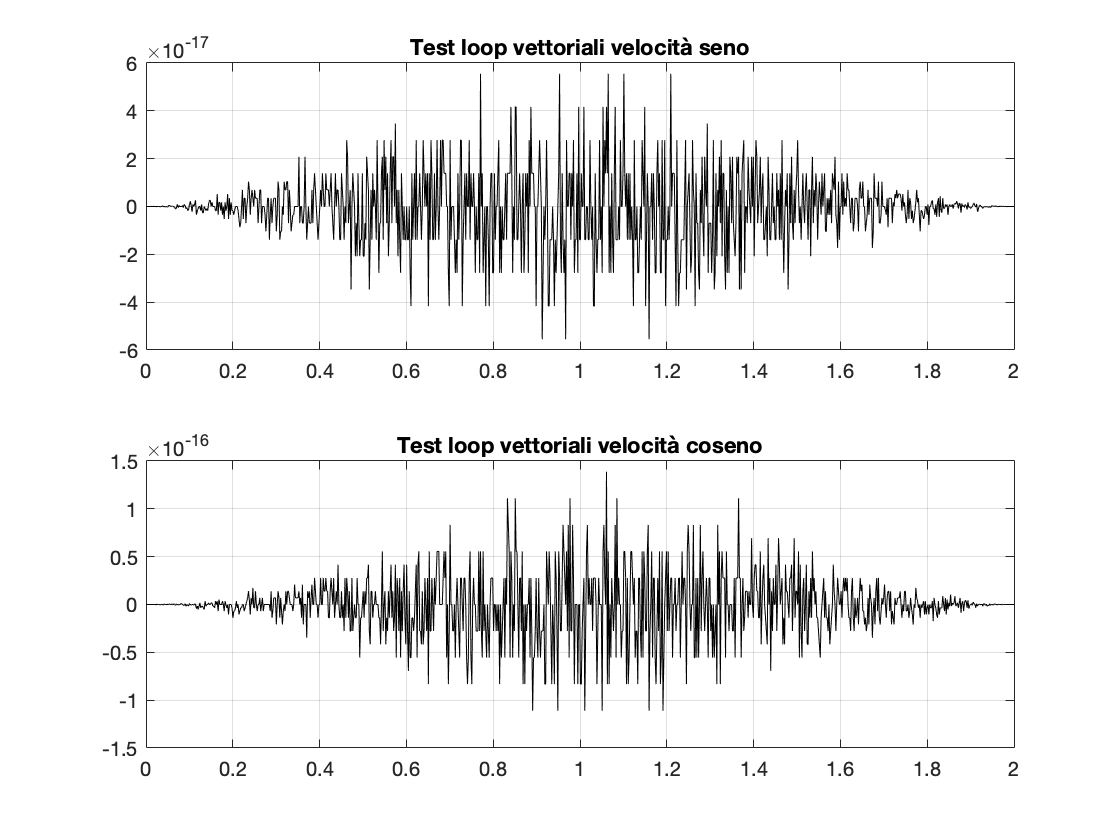

theta3_p =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017


theta4_p =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0024    0.0026    0.0027    0.0029    0.0031    0.0033    0.0034    0.0036    0.0038    0.0040    0.0042    0.0045    0.0047    0.0049    0.0051    0.0053    0.0056    0.0058    0.0061    0.0063    0.0066


J34 =    -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393
    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   

[theta3_p,theta4_p,J34] = Theta34p(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p)

**Analisi di accelerazione**

theta1ldm_pp = theta1_p + Ldm_theta1.moto.data{3,1}.v;
theta2ldm_pp = theta2_p + Ldm_theta2.moto.data{3,1}.v;
thetavldm_pp = thetaV_p + Ldm_thetav.moto.data{3,1}.v;

Theta_pp = [theta1ldm_pp;theta2ldm_pp;thetavldm_pp]

Theta_pp =          0    0.0039    0.0078    0.0117    0.0155    0.0194    0.0232    0.0269    0.0307    0.0344    0.0381    0.0418    0.0455    0.0491    0.0527    0.0563    0.0599    0.0635    0.0670    0.0705    0.0740    0.0774    0.0809    0.0843    0.0877    0.0910    0.0944    0.0977    0.1010    0.1043    0.1075    0.1107    0.1140    0.1171    0.1203    0.1235    0.1266    0.1297    0.1328    0.1358    0.1389    0.1419    0.1449    0.1478    0.1508    0.1537    0.1566    0.1595    0.1624    0.1652
         0    0.0026    0.0052    0.0078    0.0104    0.0129    0.0154    0.0180    0.0205    0.0230    0.0254    0.0279    0.0303    0.0327    0.0352    0.0376    0.0399    0.0423    0.0447    0.0470    0.0493    0.0516    0.0539    0.0562    0.0584    0.0607    0.0629    0.0651    0.0673    0.0695    0.0717    0.0738    0.0760    0.0781    0.0802    0.0823    0.0844    0.0865    0.0885    0.0905    0.0926    0.0946    0.0966    0.0986    0.1005    0.1025    0.1044    0.1063    0.10

[P_pp] = Cinematica_Diretta_Accelerazione2(PKM,Theta, Theta_p, Theta_pp, P, P_p)

P_pp =          0   -0.0009   -0.0019   -0.0028   -0.0038   -0.0047   -0.0056   -0.0065   -0.0074   -0.0083   -0.0092   -0.0101   -0.0110   -0.0119   -0.0128   -0.0136   -0.0145   -0.0154   -0.0162   -0.0171   -0.0179   -0.0188   -0.0196   -0.0204   -0.0212   -0.0220   -0.0229   -0.0237   -0.0245   -0.0253   -0.0260   -0.0268   -0.0276   -0.0284   -0.0291   -0.0299   -0.0307   -0.0314   -0.0322   -0.0329   -0.0336   -0.0344   -0.0351   -0.0358   -0.0365   -0.0372   -0.0379   -0.0386   -0.0393   -0.0400
         0   -0.0003   -0.0006   -0.0010   -0.0013   -0.0016   -0.0019   -0.0022   -0.0025   -0.0028   -0.0031   -0.0034   -0.0037   -0.0040   -0.0043   -0.0046   -0.0049   -0.0052   -0.0055   -0.0058   -0.0060   -0.0063   -0.0066   -0.0069   -0.0072   -0.0074   -0.0077   -0.0080   -0.0082   -0.0085   -0.0088   -0.0090   -0.0093   -0.0096   -0.0098   -0.0101   -0.0103   -0.0106   -0.0108   -0.0111   -0.0113   -0.0116   -0.0118   -0.0121   -0.0123   -0.0126   -0.0128   -0.0130   -0.0133  

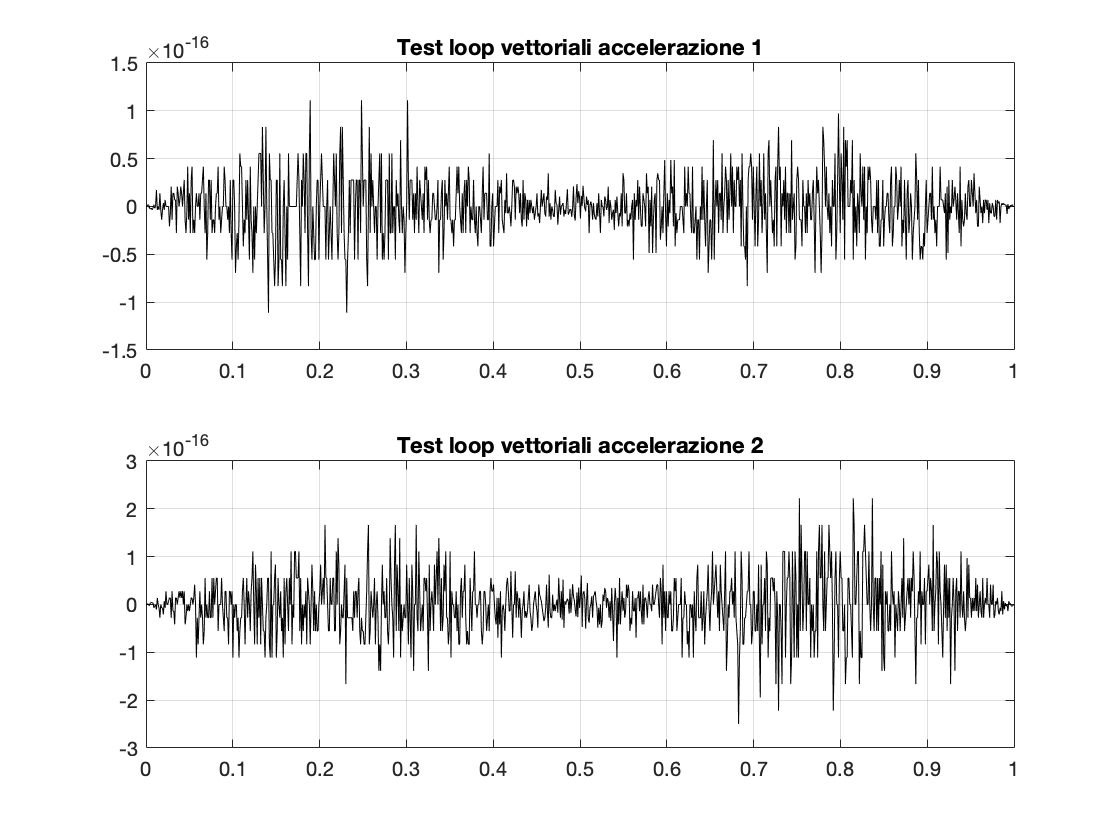

theta3_pp =          0    0.0008    0.0016    0.0024    0.0031    0.0039    0.0047    0.0054    0.0062    0.0069    0.0077    0.0084    0.0092    0.0099    0.0106    0.0114    0.0121    0.0128    0.0135    0.0142    0.0149    0.0156    0.0163    0.0170    0.0177    0.0184    0.0190    0.0197    0.0204    0.0210    0.0217    0.0223    0.0230    0.0236    0.0243    0.0249    0.0255    0.0262    0.0268    0.0274    0.0280    0.0286    0.0292    0.0298    0.0304    0.0310    0.0316    0.0322    0.0328    0.0333


theta4_pp =          0    0.0030    0.0060    0.0090    0.0119    0.0149    0.0178    0.0207    0.0236    0.0264    0.0293    0.0321    0.0349    0.0377    0.0405    0.0432    0.0460    0.0487    0.0514    0.0541    0.0568    0.0594    0.0620    0.0647    0.0673    0.0698    0.0724    0.0750    0.0775    0.0800    0.0825    0.0850    0.0874    0.0899    0.0923    0.0947    0.0971    0.0995    0.1019    0.1042    0.1065    0.1089    0.1112    0.1134    0.1157    0.1179    0.1202    0.1224    0.1246    0.1268


J34p =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0000    0.0002    0.0000    0.0002    0.0000    0.0003    0.0001    0.0003    0.0001    0.0003    0.0001    0.0004    0.0001    0.0004    0.0001    0.0005    0.0001    0.0005    0.0001    0.0006    0.0001    0.0006    0.0001    0.0007    0.0001    0.0008
         0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0002    0.0001   -0.0002    0.0001   -0.0002    0.0002   -0.0003    0.0002   -0.0004    0.0002   -0.0004    0.0003   -0.0005    0.0003   -0.0005    0.0004   -0.0006    0.0004   -0.0007    0.0004   -0.0008    0.0005   -0.0009    0.0005   -0.0010    0.0006   -0.0011    0.0007   -0.0012    0.0007   -0.0013    0.0008  

[theta3_pp,theta4_pp,J34p] = Theta34pp(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,...
    theta3_p,theta4_p,theta1ldm_pp, theta2ldm_pp,J34)


[C1_p, C2_p, C1_pp, C2_pp, E1_p, E1_pp, J1, J1p, J2, J2p, J3, J3p, J4, J4p, JE, JEp,P_p34, P_pp34] = Jacobiani(PKM, Theta, Theta_p, theta3, theta4, theta3_p, theta4_p, J34, J34p, P_pp, Theta_pp);

**Confronto cinematica analitica e derivata numerica**

%Plot_EF(PKM,P, P_p34, P_pp34, P_pM)

**Confronto cinematica matlab e adams**

% load PKM_PosEF
% load PKM_VelEF
% load PKM_AccEF
% load PKM_PosE1
% load PKM_VelE1
% load PKM_AccE1
% load PKM_Pa_VelCM
% time = linspace(0,PKM.ta,length(Theta_p));
%C1x_p_ad = PKM_Pa_VelCM(:,1);
% C1x_p_ad = C1x_p_ad';
% C1y_p_ad = PKM_Pa_VelCM(:,2);
% C1y_p_ad = C1y_p_ad';
% figure
% subplot(2,1,1);
%plot(time,C2_p(1,:)-C1x_p_ad,'color','b','linewidth',1)
% title('Errore velocità X C1 Matlab-Adams')
% grid on
% 
% subplot(2,1,2); 
% plot(time,C2_p(2,:)-C1y_p_ad,'color','b','linewidth',1)
% title('Errore velocità Y C1 Matlab-Adams')
% grid on
% Matlab_Adams_Cinematica(PKM_PosEF, P, PKM_VelEF, P_p, PKM_AccEF, P_pp, PKM_PosE1, E1, PKM_VelE1, E1_p, PKM_AccE1, E1_pp)

## Cinematica Inversa

**Analisi di posizione**

[theta1inv,theta2inv] = Cinematica_Inversa_Posizione(P, PKM, theta1ldm, theta2ldm);
Errore_theta1 = theta1ldm - theta1inv;
Errore_theta2 = theta2ldm - theta2inv;


% figure
% subplot(2,1,1);
% plot(time,Errore_theta1,'color','b')
% title('Errore theta1')
% grid on
% subplot(2,1,2); 
% plot(time,Errore_theta2,'color','b')
% title('Errore theta2')
% grid on

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1inv,theta2inv,theta3,theta4)

**Analisi di velocità**

Theta_p_inv = Cinematica_Inversa_Velocita(J,P_p);

**Analisi di accelerazione**

% Theta_pp_inv = Cinematica_Inversa_Accelerazione(J_p,J,Theta_p,P_pp);

## Dinamica

**Metodo azioni vicolari**

[C1_AV, C2_AV] = Dinamica(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,thetavldm_pp)

C1_AV =          0    0.0015    0.0029    0.0044    0.0058    0.0072    0.0086    0.0101    0.0115    0.0129    0.0142    0.0156    0.0170    0.0183    0.0197    0.0210    0.0224    0.0237    0.0250    0.0263    0.0276    0.0289    0.0302    0.0315    0.0327    0.0340    0.0352    0.0365    0.0377    0.0389    0.0401    0.0413    0.0425    0.0437    0.0449    0.0461    0.0473    0.0484    0.0496    0.0507    0.0518    0.0530    0.0541    0.0552    0.0563    0.0574    0.0585    0.0596    0.0606    0.0617


C2_AV =          0    0.0007    0.0014    0.0020    0.0027    0.0034    0.0040    0.0047    0.0053    0.0060    0.0066    0.0073    0.0079    0.0085    0.0092    0.0098    0.0104    0.0110    0.0116    0.0122    0.0128    0.0134    0.0140    0.0146    0.0152    0.0158    0.0164    0.0170    0.0175    0.0181    0.0187    0.0192    0.0198    0.0203    0.0209    0.0214    0.0220    0.0225    0.0230    0.0236    0.0241    0.0246    0.0251    0.0257    0.0262    0.0267    0.0272    0.0277    0.0282    0.0287


**Metodo PLV**

[C1_PLV, C2_PLV, M, K] = Dinamica_PLV(PKM,theta1ldm_p,theta2ldm_p,theta1ldm_pp,theta2ldm_pp,J1,J2,J3,J4,JE,J34,J1p,J2p,J3p,J4p,JEp,J34p)

C1_PLV =          0    0.0014    0.0028    0.0041    0.0055    0.0068    0.0082    0.0095    0.0109    0.0122    0.0135    0.0148    0.0161    0.0174    0.0186    0.0199    0.0212    0.0224    0.0237    0.0249    0.0261    0.0274    0.0286    0.0298    0.0310    0.0322    0.0334    0.0345    0.0357    0.0369    0.0380    0.0391    0.0403    0.0414    0.0425    0.0436    0.0447    0.0458    0.0469    0.0480    0.0491    0.0502    0.0512    0.0523    0.0533    0.0543    0.0554    0.0564    0.0574    0.0584


C2_PLV =          0    0.0007    0.0013    0.0020    0.0026    0.0033    0.0039    0.0045    0.0052    0.0058    0.0064    0.0070    0.0076    0.0083    0.0089    0.0095    0.0101    0.0107    0.0113    0.0119    0.0124    0.0130    0.0136    0.0142    0.0147    0.0153    0.0159    0.0164    0.0170    0.0175    0.0181    0.0186    0.0192    0.0197    0.0202    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0244    0.0248    0.0253    0.0258    0.0263    0.0268    0.0273    0.0278


M =     0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215
   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0

K =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0000    0.0002    0.0000
         0         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0002    0.0001   -0.0002    0.0001   -0.0002    0.0001   -0.0002    0.0001   -0.0003    0.0001   -0.0003    0.0001   -0.0003    0.0001   -0.0004    0.0001   -0.0004    0.0002   -0.0004    0

**Confronto tra i due metodi**

%ErrC1 = C1_PLV(1,:)-C1_AV(1,:);
% ErrC2 = C2_PLV(1,:)-C2_AV(1,:);
% figure
% subplot(2,1,1);
% plot(time(1,:),C1_PLV(1,:),'color','b','linewidth',1)
% title('Coppia theta1 PLV')
% grid on
% subplot(2,1,2);
% plot(time(1,:),C2_PLV(1,:),'color','k','linewidth',1)
% title('Coppia theta2 PLV')
% grid on

**Confronto dinamica Matlab-Adams**

% load PKM_Pa_CoppieNOEF
% Matlab_Adams_Dinamica(PKM_Pa_CoppieNOEF, -C1_PLV, -C2_PLV)

**Dinamica inversa calcolo Coppie**

Condizioni = [theta1ldm(1,1),theta2ldm(1,1),theta1ldm_p(1,1),theta2ldm_p(1,1)]

Condizioni =     2.0944    1.0472         0         0


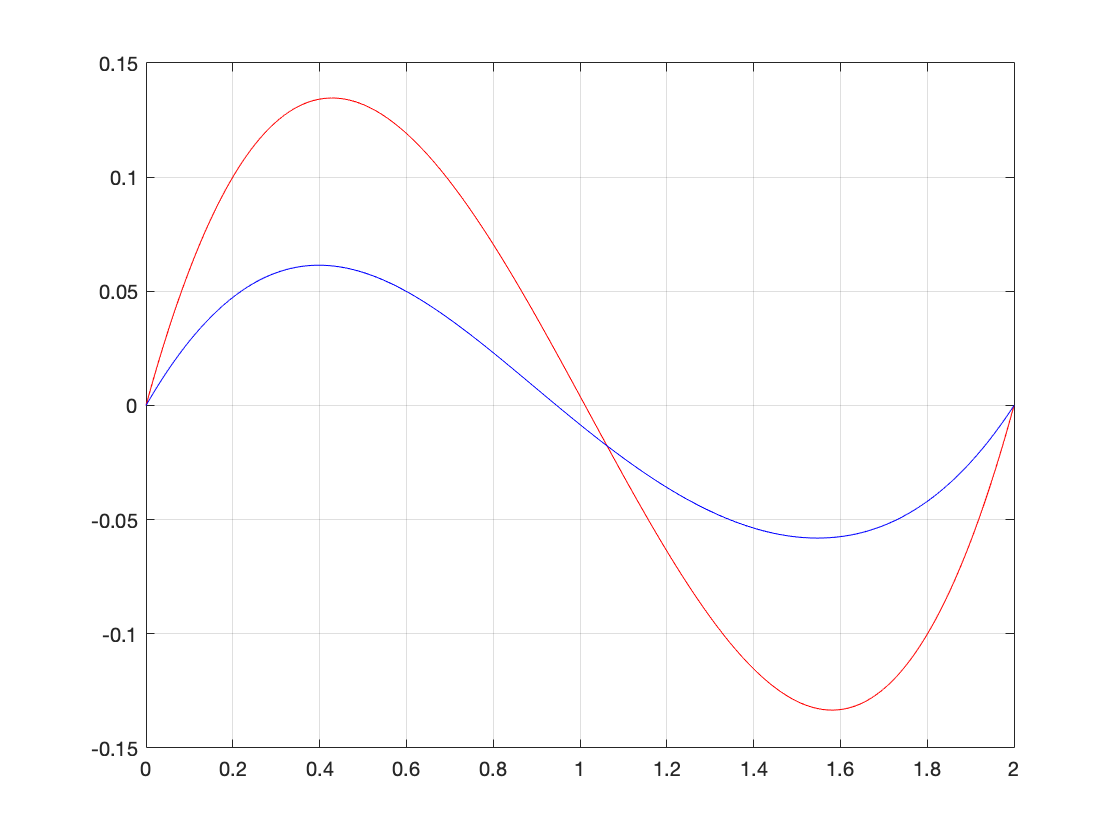

[ThetaInt,Theta_pInt,Theta_ppInt] =  DinamicaInversa([C1_PLV;C2_PLV],Condizioni);

figure
plot(linspace(0,time(end),1000),C1_PLV,"Color","red")
hold on 
grid on
plot(linspace(0,time(end),1000),C2_PLV,"Color","b")

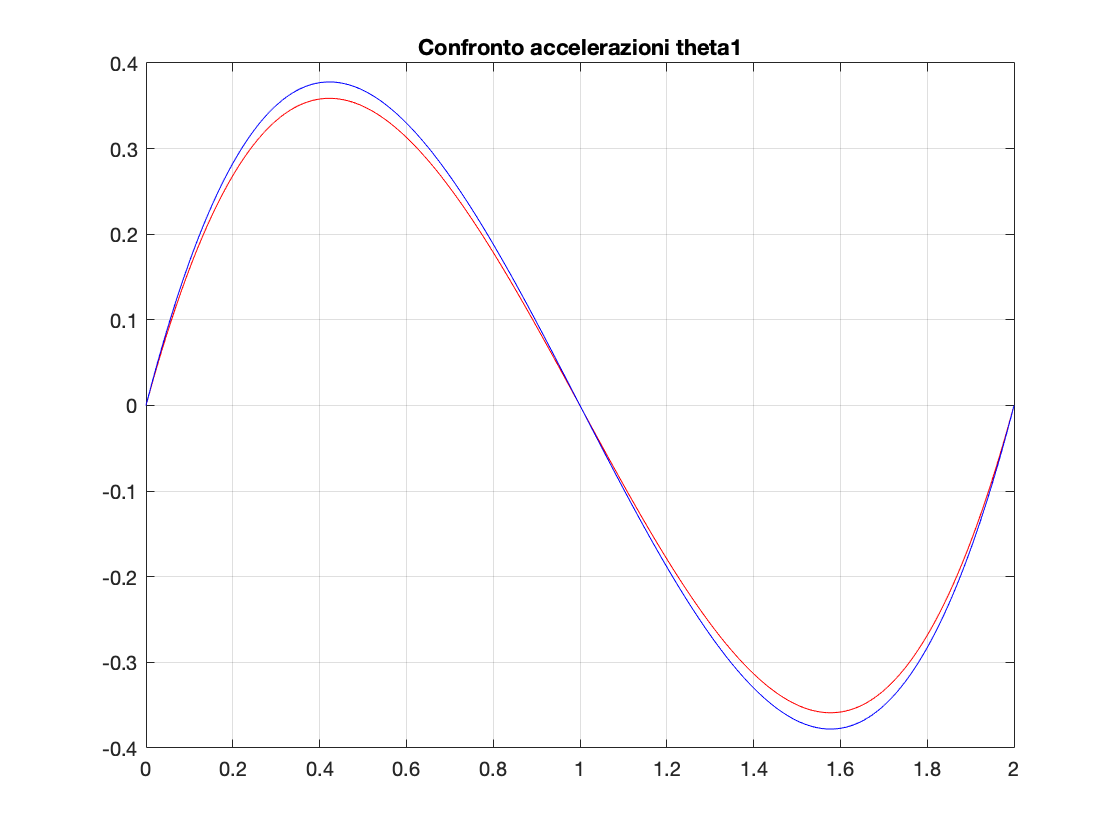

figure
plot(linspace(0,time(end),1000),Theta_ppInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,time(end),1000),theta1ldm_pp(1,:),"Color","b")
title('Confronto accelerazioni theta1')

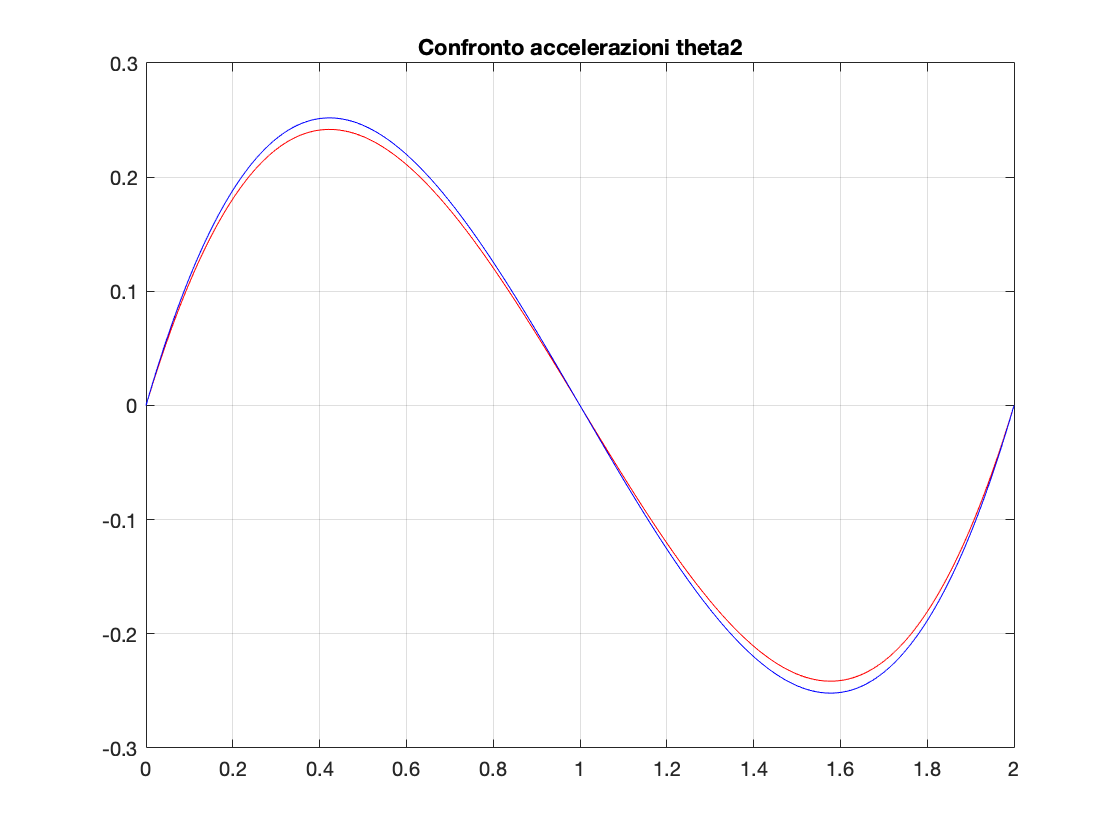

figure
plot(linspace(0,time(end),1000),Theta_ppInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,time(end),1000),theta2ldm_pp(1,:),"Color","b")
title('Confronto accelerazioni theta2')

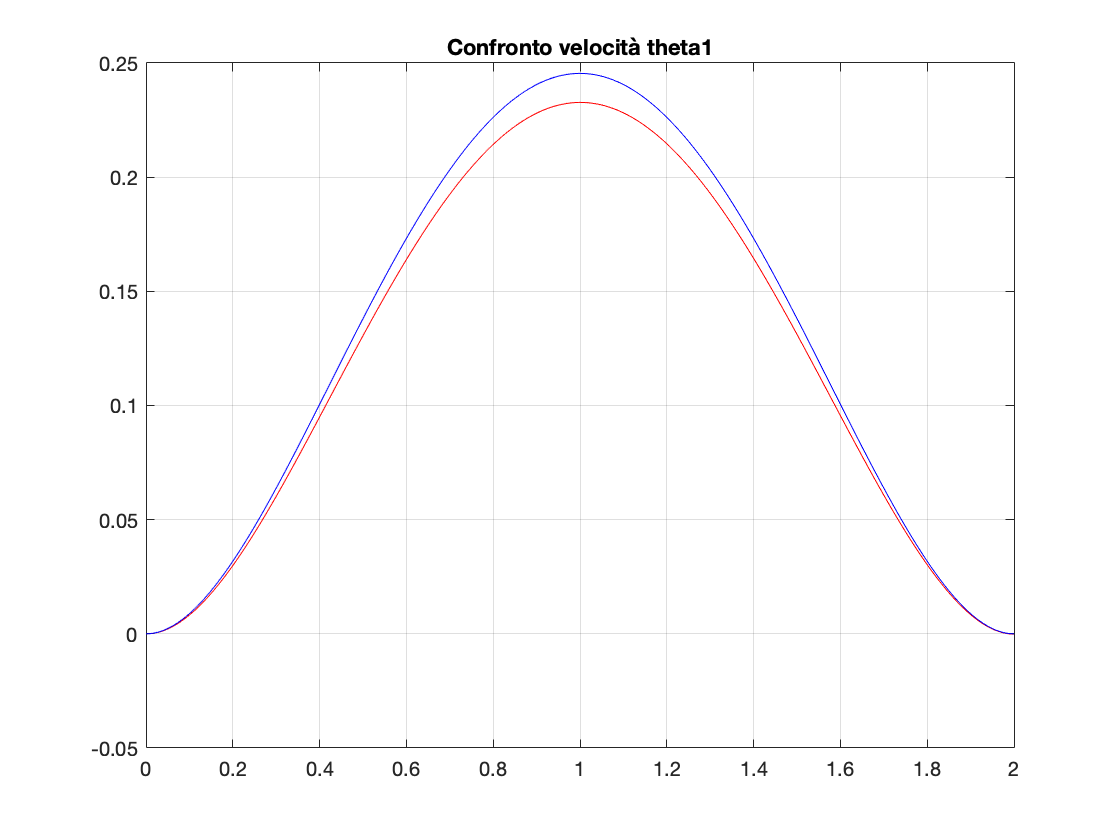

figure
plot(linspace(0,time(end),1000),Theta_pInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,time(end),1000),theta1ldm_p(1,:),"Color","b")
title('Confronto velocità theta1')

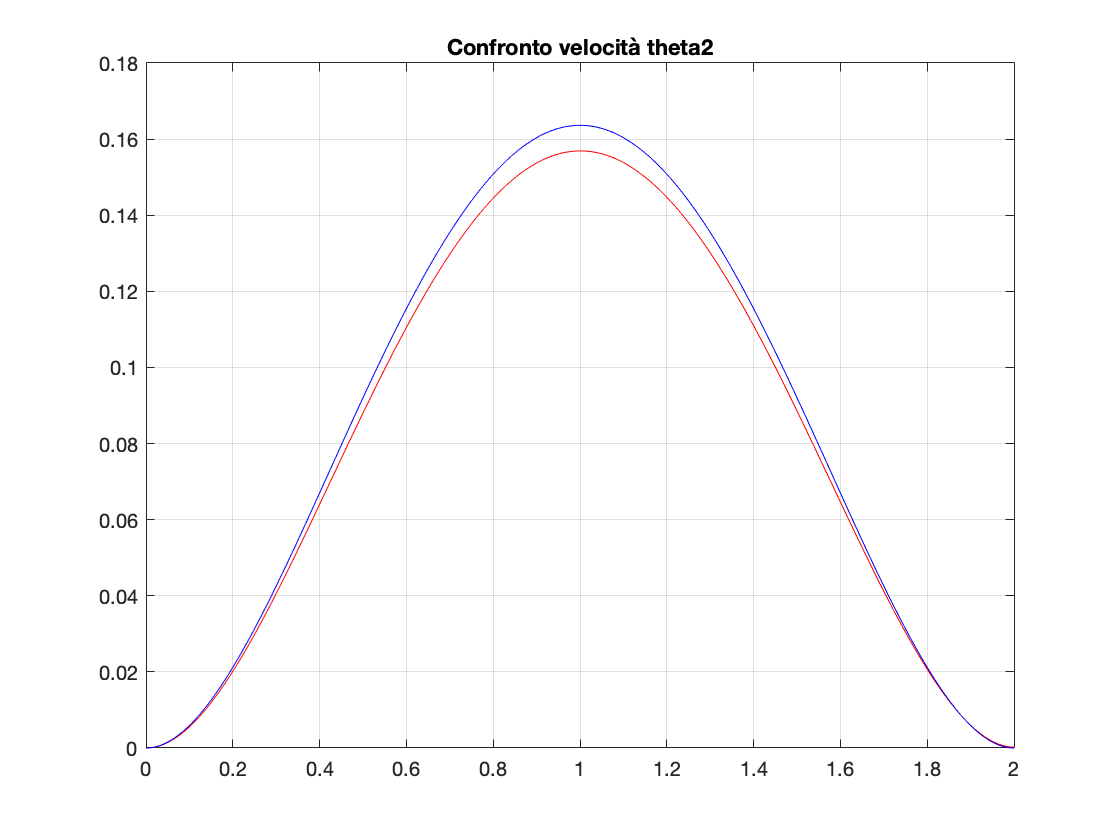

figure
plot(linspace(0,time(end),1000),Theta_pInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,time(end),1000),theta2ldm_p(1,:),"Color","b")
title('Confronto velocità theta2')

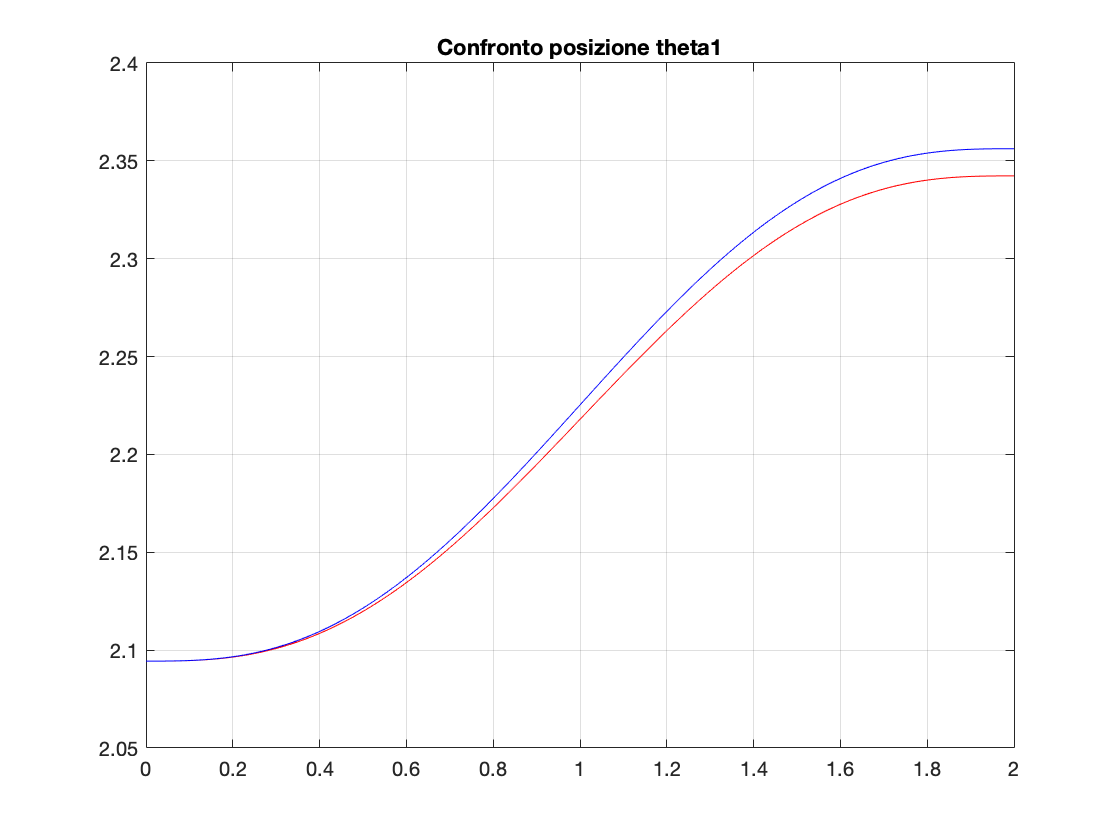


figure
plot(linspace(0,time(end),1000),ThetaInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,time(end),1000),theta1ldm(1,:),"Color","b")
title('Confronto posizione theta1')

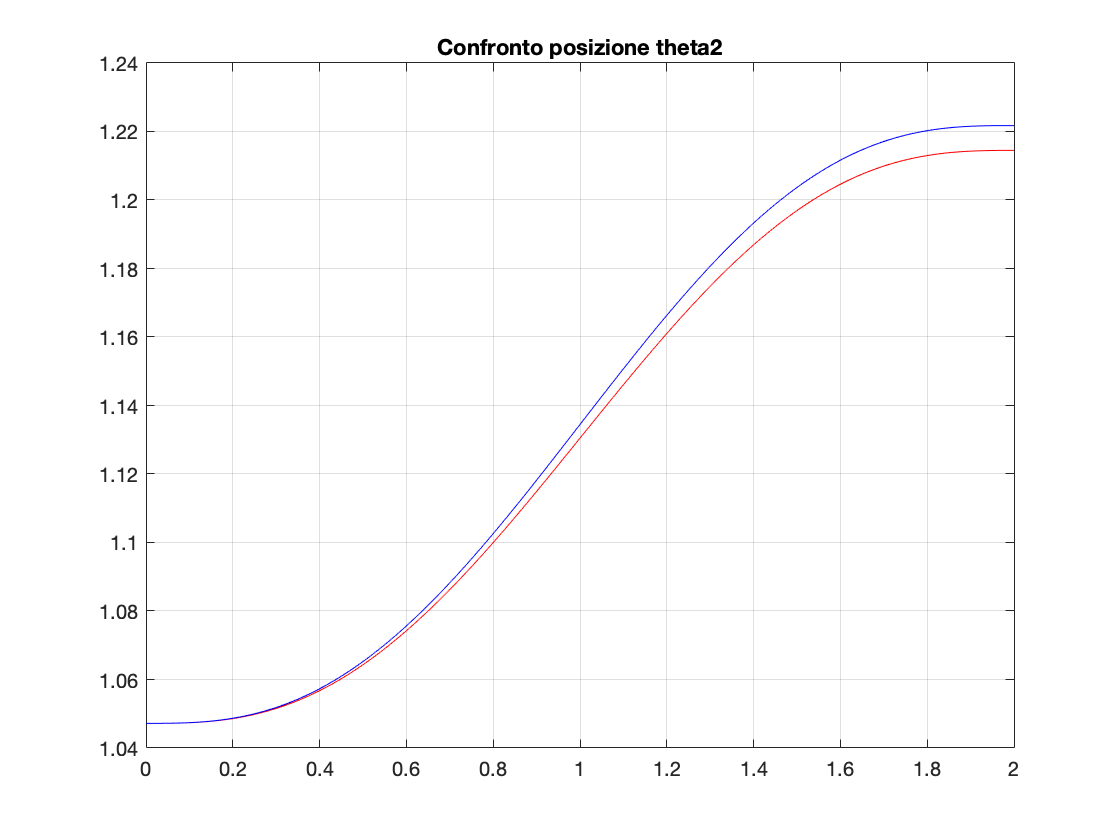

figure
plot(linspace(0,time(end),1000),ThetaInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,time(end),1000),theta2ldm(1,:),"Color","b")
title('Confronto posizione theta2')

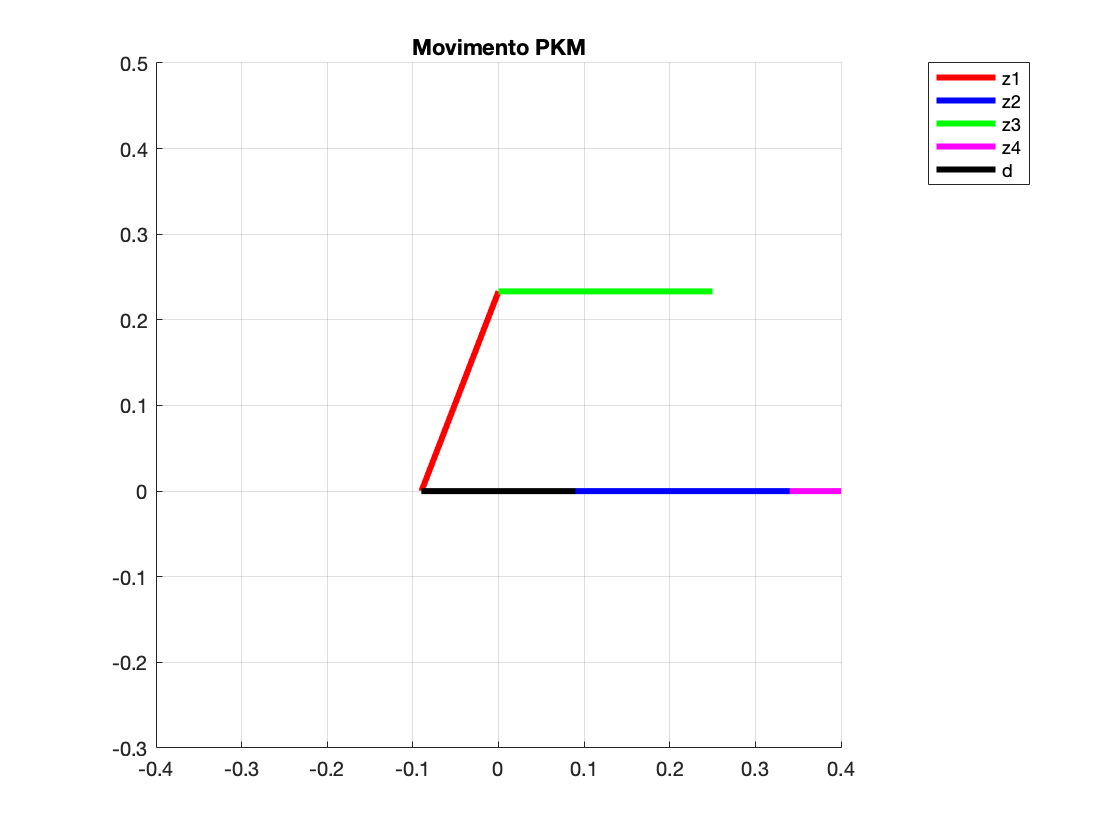

[test1,test2] = Singolarita(time)